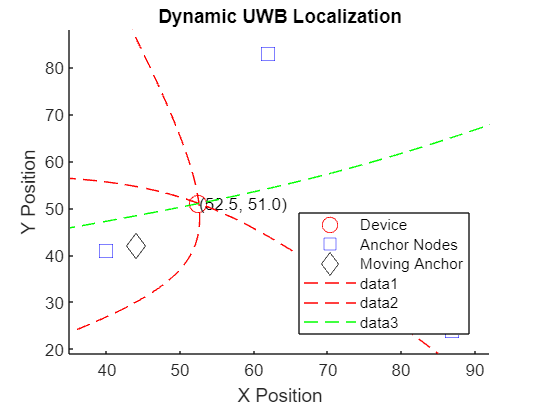

% Define initial positions for device and anchor nodes
deviceLocInitial = [50 50];  % Initial device position
nodeLocInitial = [40 41;     % Initial anchor node positions
                  62 83;
                  87 24];

% Define velocity for device and the moving anchor node
deviceVelocity = [0.5, 0.2];   % Velocity of the device in x and y directions
anchorVelocity = [0.8, 0.2];   % Velocity of the moving anchor in x and y directions

% Number of anchor nodes
numNodes = size(nodeLocInitial, 1);

% Simulation parameters
numTimeSteps = 50;  % Number of time steps for simulation
timeStep = 0.1;      % Time step duration (adjust as needed)
SNR = 10;            % Signal-to-Noise Ratio

% Initialize device and anchor node positions
deviceLoc = deviceLocInitial;
nodeLoc = nodeLocInitial;

% Initialize plot variables
figure;
hold on;
xlabel('X Position');
ylabel('Y Position');
title('Dynamic UWB Localization');
axis tight;

% Initialize plot limits
minX = min([deviceLocInitial(1), nodeLocInitial(:, 1)']);
maxX = max([deviceLocInitial(1), nodeLocInitial(:, 1)']);
minY = min([deviceLocInitial(2), nodeLocInitial(:, 2)']);
maxY = max([deviceLocInitial(2), nodeLocInitial(:, 2)']);
margin = 5; % Margin for zooming
axis([minX-margin maxX+margin minY-margin maxY+margin]);

% Plot initial positions of device and anchor nodes
devicePlot = plot(deviceLocInitial(1), deviceLocInitial(2), 'ro', 'MarkerSize', 10, 'DisplayName', 'Device');
nodePlot = plot(nodeLocInitial(:, 1), nodeLocInitial(:, 2), 'bs', 'MarkerSize', 10, 'DisplayName', 'Anchor Nodes');

% Initialize text annotation for device coordinates
deviceText = text(deviceLocInitial(1), deviceLocInitial(2), sprintf('(%.1f, %.1f)', deviceLocInitial), 'HorizontalAlignment', 'left');

% Initialize dynamic plot handles for hyperbolas
hyperbolaPlots = gobjects(numNodes, numNodes);

% Initialize plot handle for the moving anchor
movingAnchorPlot = plot(nodeLocInitial(1, 1), nodeLocInitial(1, 2), 'kd', 'MarkerSize', 10, 'DisplayName', 'Moving Anchor');

% Define plot styles for hyperbolas
plotStr = {'r--', 'g--', 'b--'};

for t = 1:numTimeSteps
    % Update device position
    deviceLoc = deviceLoc + deviceVelocity * timeStep;
    
    % Update moving anchor position
    nodeLoc(1, :) = nodeLoc(1, :) + anchorVelocity * timeStep;
    
    % Update plot positions
    set(devicePlot, 'XData', deviceLoc(1), 'YData', deviceLoc(2));
    set(movingAnchorPlot, 'XData', nodeLoc(1, 1), 'YData', nodeLoc(1, 2));
    
    % Update text annotation for device coordinates
    set(deviceText, 'Position', [deviceLoc(1), deviceLoc(2)], 'String', sprintf('(%.1f, %.1f)', deviceLoc));
    
    % Update plot limits dynamically to focus on changing positions
    minX = min([minX, deviceLoc(1), nodeLoc(:, 1)']);
    maxX = max([maxX, deviceLoc(1), nodeLoc(:, 1)']);
    minY = min([minY, deviceLoc(2), nodeLoc(:, 2)']);
    maxY = max([maxY, deviceLoc(2), nodeLoc(:, 2)']);
    axis([minX-margin maxX+margin minY-margin maxY+margin]);
    
    % Recalculate hyperbolas for current device position
    for node1 = 1:numNodes
        for node2 = (node1+1):numNodes
            % Calculate Time Difference of Arrival (TDOA)
            TDOA(node1, node2) = actualTOF(node1, deviceLoc, nodeLoc) - actualTOF(node2, deviceLoc, nodeLoc);

            % Get hyperbolic surface for the TDOA between node1 and node2
            [x{node1, node2}, y{node1, node2}] = helperGetHyperbolicSurface( ...
                nodeLoc(node1,:), ...
                nodeLoc(node2,:), ...
                TDOA(node1,node2));
            
            % Update hyperbola plot
            if ishandle(hyperbolaPlots(node1, node2))
                set(hyperbolaPlots(node1, node2), 'XData', x{node1, node2}, 'YData', y{node1, node2});
            else
                hyperbolaPlots(node1, node2) = plot(x{node1, node2}, y{node1, node2}, plotStr{node1});
            end
        end
    end
    
    % Draw plot
    drawnow;

    % Pause for visualization (optional)
    pause(0.1);
end

% Add legend
legend('Location', 'best');

function tof = actualTOF(node, deviceLoc, nodeLoc)
% Function to compute the Time of Flight (TOF) for each anchor node
% This is a hypothetical function, replace it with your actual computation
% Distance between device and the specified anchor node
distance = sqrt(sum((nodeLoc(node, :) - deviceLoc).^2));
% Assuming speed of signal propagation (e.g., speed of light)
c = physconst('LightSpeed'); % speed of light (m/s)

% Calculate TOF
tof = distance / c;

SNR = 30;  % in dB sound to noise ratio
end
